addpath('Kinematics')
addpath('Kinetics')
addpath('Control System')
addpath('Setpoint Control No FF')


supressed_print= evalc('run Linearize_EOMs.mlx'); %Run the script to generate the equations of motion for the Ball and Plate in terms of the u-joint torques

clear supressed_print

sympref('FloatingPoint',true);

# Linear Moving Setpoint Controller With Error Polynomial Setting

EXPLANATION HERE

## Reformulate the System as Two Decoupled, Fourth Order, Single Input Systems

A system with state vector $\tilde{x}_{1} $:


$$\tilde{x}_{1} = [x ~\dot{x} ~\beta ~\dot{\beta}]^T

$$


And state equation:


$$\dot{\tilde{x}}_{1} = A_{1} \tilde{x}_{1} + B_{1}\tilde{u}_{1}$$


A1 = A_uc(1:4,1:4)

$$A1 = \left[\begin{array}{cccc} 0 & 1 & 0 & 0\\ -5.2170 & 0 & 4.0111 & 0\\ 0 & 0 & 0 & 1\\ 112.8871 & 0 & 64.8295 & 0 \end{array}\right]$$

B1 = B_uc(1:4,1)

$$B1 = \left[\begin{array}{c} 0\\ -17.7268\\ 0\\ 383.5785 \end{array}\right]$$

And another system with state vector $\tilde{x}_{2} $:


$$\tilde{x}_{2} = [y~\dot{y}~\gamma~\dot{\gamma}]^T$$


And state equation:


$$\dot{\tilde{x}}_{2} = A_{2} \tilde{x}_{2} + B_{2}\tilde{u}_{2}$$


A2 = A_uc(5:8,5:8)

$$A2 = \left[\begin{array}{cccc} 0 & 1 & 0 & 0\\ -5.2170 & 0 & -4.0111 & 0\\ 0 & 0 & 0 & 1\\ -112.8871 & 0 & 64.8295 & 0 \end{array}\right]$$

B2 = B_uc(5:8,2)

$$B2 = \left[\begin{array}{c} 0\\ 17.7268\\ 0\\ 383.5785 \end{array}\right]$$

EOMS1 = stateVec1_dot == A1*stateVec1 + B1*T_beta

$$EOMS1 = \left[\begin{array}{c} \dot{x}=\dot{x}\\ \ddot{x}=-5.2170\,x+4.0111\,\beta -17.7268\,T_{\beta }\\ \dot{\beta }=\dot{\beta }\\ \ddot{\beta }=112.8871\,x+64.8295\,\beta +383.5785\,T_{\beta } \end{array}\right]$$

EOMS2 = stateVec2_dot == A2*stateVec2 + B2*T_gamma

$$EOMS2 = \left[\begin{array}{c} \dot{y}=\dot{y}\\ \ddot{y}=-5.2170\,y-4.0111\,\gamma +17.7268\,T_{\gamma }\\ \dot{\gamma }=\dot{\gamma }\\ \ddot{\gamma }=-112.8871\,y+64.8295\,\gamma +383.5785\,T_{\gamma } \end{array}\right]$$

## Augmented System For State Space Representation of PID Controller

An augmented state vector is used in the absolute states. An additional term, the integral of postion, is used so that there is an analagous element to the integral term in the error state vector utilized later:


$$\tilde{x}_{1a} = [
 \int_0^t \!x\, \mathrm{d}t~x ~\dot{x} ~\beta~\dot{\beta}]^T


$$


$A_{1a}$ is the $A_1$ matrix modified to contain the dynamics of the $\int_{0}^{t}xdt~$term. This term's dynamics are simply that its derivative is the $x$ position of the ball. 

A1a = [[0 1 0 0 0];[zeros(4,1),A1]] %Augmented A1 Matrix

$$A1a = \left[\begin{array}{ccccc} 0 & 1 & 0 & 0 & 0\\ 0 & 0 & 1 & 0 & 0\\ 0 & -5.2170 & 0 & 4.0111 & 0\\ 0 & 0 & 0 & 0 & 1\\ 0 & 112.8871 & 0 & 64.8295 & 0 \end{array}\right]$$

$B_{1a}$ is the direct influence of the actuation torque on the system. Since the integral of position is not a direct function of this signal, the augmented matrix recieves another zero element. 

B1a = [0;B1]

$$B1a = \left[\begin{array}{c} 0\\ 0\\ -17.7268\\ 0\\ 383.5785 \end{array}\right]$$


stateVec1a = [ix, x, x_dot, beta, beta_dot].'

$$stateVec1a = \left[\begin{array}{c} \mathrm{ix}\\ x\\ \dot{x}\\ \beta \\ \dot{\beta } \end{array}\right]$$

stateVec1a_dot = [x, x_dot, x_ddot, beta_dot, beta_ddot].'

$$stateVec1a\_dot = \left[\begin{array}{c} x\\ \dot{x}\\ \ddot{x}\\ \dot{\beta }\\ \ddot{\beta } \end{array}\right]$$


EOM1a = stateVec1a_dot == A1a*stateVec1a + B1a*T_beta

$$EOM1a = \left[\begin{array}{c} x=x\\ \dot{x}=\dot{x}\\ \ddot{x}=-5.2170\,x+4.0111\,\beta -17.7268\,T_{\beta }\\ \dot{\beta }=\dot{\beta }\\ \ddot{\beta }=112.8871\,x+64.8295\,\beta +383.5785\,T_{\beta } \end{array}\right]$$

## Set the Characteristic Polynomial for the Error States Using Pole Placement for Convenience

A1e = [0 1 0;0 0 1; 0 0 0]

A1e =      0     1     0
     0     0     1
     0     0     0


B1e = [0;0;1]

B1e =      0
     0
     1


ans = 3

syms K1 K2 K3
K1e = [K1 K2 K3] %Make the K1e mastrix symbolic and fill with results from place later

$$K1e = \left[\begin{array}{ccc} K_{1} & K_{2} & K_{3} \end{array}\right]$$

## Derive the Associated Feedback Law

First, define a characteristic polynomial in homogenous error dynamics. Utilize a pole placement approch to parameterize its behavior. 

char_poly_ex_eqn = e_x_ddot - [0 0 1]*((A1e-B1e*K1e)*[e_ix e_x e_x_dot].') == 0

$$char\_poly\_ex\_eqn = K_{2}\,e_{x}+e_{\ddot{x}}+K_{3}\,e_{\dot{x}}+K_{1}\,e_{\mathrm{ix}}=0$$

Substitute the error states for absolute states and setpoint states. 

char_poly_ex_eqn = subs(char_poly_ex_eqn, [e_x_ddot e_x_dot e_x e_ix], [x_ddot_s - x_ddot, x_dot_s - x_dot , x_s - x, ix_s - ix])

$$char\_poly\_ex\_eqn = {\ddot{x}}_{s}-\ddot{x}-K_{1}\,\left(\mathrm{ix}-{\mathrm{ix}}_{s}\right)-K_{2}\,\left(x-x_{s}\right)-K_{3}\,\left(\dot{x}-{\dot{x}}_{s}\right)=0$$

Substitute in the equation for $\ddot{x}$ from the augmented dynamics - brings in the system's physics. 

char_poly_ex_eqn = subs(char_poly_ex_eqn, x_ddot, rhs(EOMS1(2))) %Replace x_ddot with its dynamic equation

$$char\_poly\_ex\_eqn = 17.7268\,T_{\beta }-4.0111\,\beta +5.2170\,x+{\ddot{x}}_{s}-K_{1}\,\left(\mathrm{ix}-{\mathrm{ix}}_{s}\right)-K_{2}\,\left(x-x_{s}\right)-K_{3}\,\left(\dot{x}-{\dot{x}}_{s}\right)=0$$

The feedback law is the torque $T_\beta$ required to produce the error dynamics specified. 

FB_Law_T_beta = isolate(char_poly_ex_eqn, T_beta)

$$FB\_Law\_T\_beta = T_{\beta }=0.2263\,\beta -0.2943\,x-0.0564\,{\ddot{x}}_{s}+0.0564\,K_{1}\,\left(\mathrm{ix}-{\mathrm{ix}}_{s}\right)+0.0564\,K_{2}\,\left(x-x_{s}\right)+0.0564\,K_{3}\,\left(\dot{x}-{\dot{x}}_{s}\right)$$

Formulate the feedback law as a matrix equation (for Simulink purposes)

M1 = equationsToMatrix(rhs(FB_Law_T_beta), stateVec1a)

$$M1 = \left[\begin{array}{ccccc} 0.0564\,K_{1} & 0.0564\,K_{2}-0.2943 & 0.0564\,K_{3} & 0.2263 & 0 \end{array}\right]$$

setpointVec1 = [ix_s x_s x_dot_s].'

$$setpointVec1 = \left[\begin{array}{c} {\mathrm{ix}}_{s}\\ x_{s}\\ {\dot{x}}_{s} \end{array}\right]$$

M2 = equationsToMatrix(rhs(FB_Law_T_beta), setpointVec1)

$$M2 = \left[\begin{array}{ccc} -0.0564\,K_{1} & -0.0564\,K_{2} & -0.0564\,K_{3} \end{array}\right]$$

## Determine Whether or not the Feedback Stabilizes the System

EOM1aFB = stateVec1a_dot == A1a*stateVec1a + B1a*rhs(FB_Law_T_beta)

$$EOM1aFB = \left[\begin{array}{c} x=x\\ \dot{x}=\dot{x}\\ \ddot{x}={\ddot{x}}_{s}-K_{1}\,\left(\mathrm{ix}-{\mathrm{ix}}_{s}\right)-K_{2}\,\left(x-x_{s}\right)-K_{3}\,\left(\dot{x}-{\dot{x}}_{s}\right)\\ \dot{\beta }=\dot{\beta }\\ \ddot{\beta }=151.6229\,\beta -21.6383\,{\ddot{x}}_{s}+21.6383\,K_{1}\,\left(\mathrm{ix}-{\mathrm{ix}}_{s}\right)+21.6383\,K_{2}\,\left(x-x_{s}\right)+21.6383\,K_{3}\,\left(\dot{x}-{\dot{x}}_{s}\right) \end{array}\right]$$

CL_A_mat = equationsToMatrix(rhs(EOM1aFB), stateVec1a)

$$CL\_A\_mat = \left[\begin{array}{ccccc} 0 & 1 & 0 & 0 & 0\\ 0 & 0 & 1 & 0 & 0\\ -K_{1} & -K_{2} & -K_{3} & 0 & 0\\ 0 & 0 & 0 & 0 & 1\\ 21.6383\,K_{1} & 21.6383\,K_{2} & 21.6383\,K_{3} & 151.6229 & 0 \end{array}\right]$$

CL_eigs = simplify(eig(CL_A_mat));

% Interestingly enough, placing the poles of the error dynamics puts the poles ...
% of the closed loop system at those locations and two unchangable pole locations...
% (Likely the beta related poles). It would seem like, without stabilizing negative
% feedback from the beta states, they just are what they are regardless of what x is
% doing? I'm really not sure here
subs(CL_eigs,[K1 K2 K3],place(A1e,B1e, [-1 -2 -3])) 

$$ans = \left[\begin{array}{c} -1\\ -12.3135\\ 12.3135\\ -2\\ -3 \end{array}\right]$$

M1 = subs(M1 ,[K1 K2 K3],place(A1e,B1e, [-1 -2 -3]))

$$M1 = \left[\begin{array}{ccccc} 0.3385 & 0.3262 & 0.3385 & 0.2263 & 0 \end{array}\right]$$

M2 = subs(M2 ,[K1 K2 K3],place(A1e,B1e, [-1 -2 -3]))

$$M2 = \left[\begin{array}{ccc} -0.3385 & -0.6205 & -0.3385 \end{array}\right]$$

## Create Data and Functions for Simulation (Moving Setpoint Controller)

A1a_sim = double(A1a);
B1a_sim = double(B1a);
M1_sim = double(M1);
M2_sim = double(M2);
C1_polyset = [1 0 0 0  0; 0 1 0 0 0 ; 0 0 1 0 0];

C1_polyset =      1     0     0     0     0
     0     1     0     0     0
     0     0     1     0     0


### Moving Setpoint Parameters

r_sim = 150; % radius of circular trajectory [mm]
omega_sim =  2*pi/4; %angular frequency of circular trajectory 

des_traj_sym(t) = r_sim*sin(omega_sim*t);

### Overlay a fist order response so that the desired trajectory is smoothed out a bit

T = (2*pi/omega_sim)/5; %Time constant of the first order response that smooths out the trajectory
des_traj_sym(t) = (1 - exp(-(t/T)))*des_traj_sym;
int_des_traj_sym(t) = int(des_traj_sym,t,0,t)

$$int\_des\_traj\_sym(t) = 37.2218\,{\mathrm{e}}^{-1.2500\,t}\,\left(1.5708\,\cos\left(1.5708\,t\right)+1.2500\,\sin\left(1.5708\,t\right)\right)-95.4930\,\cos\left(1.5708\,t\right)+37.0252$$

int_des_traj_sym(0)

$$ans = 0$$

diff_des_traj_sym(t) = diff(des_traj_sym(t),t)

$$diff\_des\_traj\_sym(t) = 187.5000\,{\mathrm{e}}^{-1.2500\,t}\,\sin\left(1.5708\,t\right)-235.6194\,\cos\left(1.5708\,t\right)\,\left({\mathrm{e}}^{-1.2500\,t}-1\right)$$

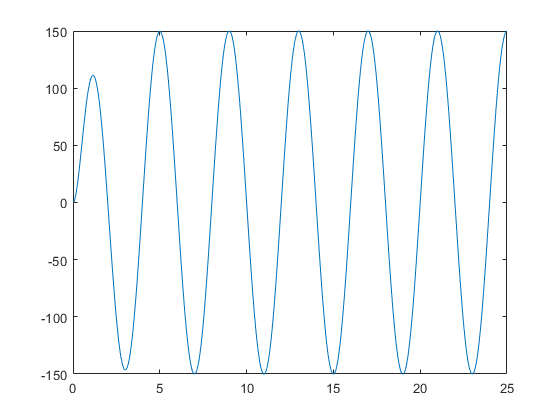

fplot(des_traj_sym) 
xlim([0 25]);

des_traj_handle = matlabFunction([int_des_traj_sym(t);des_traj_sym(t);diff_des_traj_sym(t)]);

## Simulate the Controller and Find Out if the Unstable Pole is Actually an Issue

%Specify simulation time
t_sim = 2*pi/omega_sim;
%Specify initial conditions
x1a_0 = [0 0 0 0 0]; %As if the ball was at rest in the center of the plate - the control objective of any regulator designed for the system
%Select setpoint type
SP_sel = 1; %Sinusoidal input

out = sim('Linear_Moving_Setpoint_Poly_Setting')

out =   Simulink.SimulationOutput:

                   tout: [971x1 double] 
                    x1a: [971x5 double] 
                     y1: [971x3 double] 

     SimulationMetadata: [1x1 Simulink.SimulationMetadata] 
           ErrorMessage: [0x0 char] 
